# 62743 DSP — Week 12 Tuesday

% Multirate DSP: Down-sampling & Up-sampling
% Exercises 1 & 2 from "62743 E25 Digital Signal Processing Uge 12 Tirsdag.pdf"

clear; close all; clc;


%  General paths (for Obsidian image embedding)

imgDir = 'C:\Users\Mads2\DTU\Obsidian\Courses\DSP\Images';
if ~exist(imgDir, 'dir')
    mkdir(imgDir);
end


%  Common signal setup (used in both Exercise 1 and 2)

Fs   = 8000;             % Sampling frequency [Hz]
N    = 2^14;             % Number of samples
n    = 0:N-1;            % Sample indices
t    = n/Fs;             % Time [s]

A1   = 5;                % Amplitude of tone 1
A2   = 4;                % Amplitude of tone 2
F1   = 1000;             % Tone 1 frequency [Hz]
F2   = 3500;             % Tone 2 frequency [Hz]

% Discrete-time sampled signal x[n]
x = A1*cos(2*pi*F1*t) + A2*cos(2*pi*F2*t);

% FFT setup (for spectra)
Nfft = N;
f_axis = (0:Nfft-1)*Fs/Nfft;     % 0..Fs-Δf [Hz]
X = fft(x, Nfft);
Xmag = abs(X)/Nfft;

% One-sided spectrum (0..Fs/2)
f_pos      = f_axis(1:Nfft/2+1);
Xmag_pos   = 2*Xmag(1:Nfft/2+1);   % factor 2 for one-sided magnitude


## Exercise 1 — Down-sampling by factor M = 2

## === Exercise 1-A: Sampled signal and TWO-SIDED spectrum at Fs = 8 kHz ===


fprintf('Exercise 1-A:\n');

Exercise 1-A:


fprintf('  F_s = %d Hz, N = %d samples\n', Fs, N);

  F_s = 8000 Hz, N = 16384 samples


fprintf('  T_s = %.3e s\n\n', 1/Fs);

  T_s = 1.250e-04 s



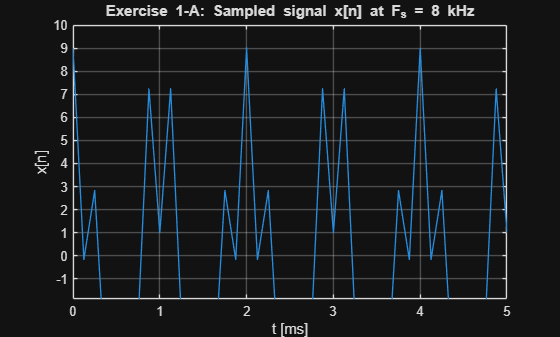


% (a) Time-domain view (zoom to first few ms for readability)
figure;
plot(t*1e3, x, 'LineWidth', 1.0); grid on;
xlim([0 5]);    % first 5 ms
xlabel('t [ms]');
ylabel('x[n]');
title('Exercise 1-A: Sampled signal x[n] at F_s = 8 kHz');

exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_1A_time_signal.png'), 'Resolution', 300);

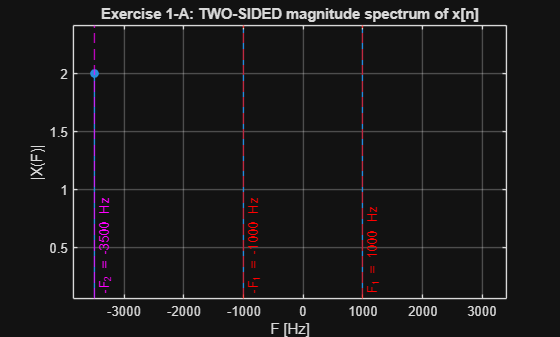


% ---------- (b) TWO-SIDED magnitude spectrum vs frequency (-Fs/2..Fs/2) ----------
Nfft   = N;
X      = fft(x, Nfft);

% fftshift to center DC at 0 Hz and get negative freqs on the left
X_shift     = fftshift(X);
Xmag_shift  = abs(X_shift)/Nfft;        % scale by N for amplitude

% Frequency axis from -Fs/2 to Fs/2 - ΔF
df     = Fs/Nfft;
f_axis = (-Nfft/2 : Nfft/2-1) * df;     % same length as X_shift

figure;
stem(f_axis, Xmag_shift, 'filled'); grid on; hold on;
xline(F1,  '--r', sprintf('F_1 = %d Hz',  F1),  'LabelVerticalAlignment','bottom');
xline(-F1, '--r', sprintf('-F_1 = -%d Hz', F1), 'LabelVerticalAlignment','bottom');
xline(F2,  '--m', sprintf('F_2 = %d Hz',  F2),  'LabelVerticalAlignment','bottom');
xline(-F2, '--m', sprintf('-F_2 = -%d Hz', F2), 'LabelVerticalAlignment','bottom');

xlabel('F [Hz]');
ylabel('|X(F)|');
title('Exercise 1-A: TWO-SIDED magnitude spectrum of x[n]');
xlim([-4000 4000]);     % show both negative and positive up to Nyquist
ylim([0 2.6]);
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_1A_mag_spectrum_twosided.png'), 'Resolution', 300);

## Exercise 1-B: Naive down-sampling by M = 2 (no anti-alias filter)

M = 2;                       % Down-sampling factor
Fs_D = Fs/M;                 % New sampling frequency [Hz]
Fmax_D = Fs_D/2;             % New Nyquist frequency [Hz]

fprintf('Exercise 1-B:\n');

Exercise 1-B:


fprintf('  Down-sampling factor M = %d\n', M);

  Down-sampling factor M = 2


fprintf('  New sampling rate F_s'' = %.0f Hz\n', Fs_D);

  New sampling rate F_s' = 4000 Hz


fprintf('  New Nyquist frequency F_{max}'' = %.0f Hz\n\n', Fmax_D);

  New Nyquist frequency F_{max}' = 2000 Hz



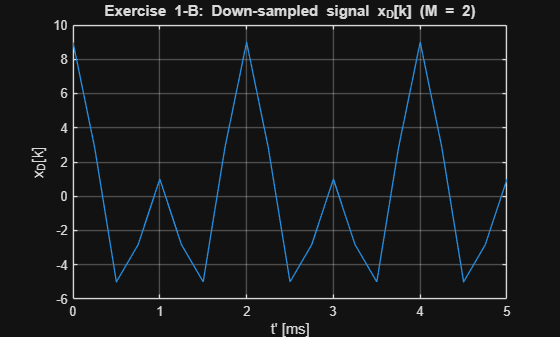


% Down-sampled signal x_D[k] = x[Mk]
xD = x(1:M:end);
ND = numel(xD);
kD = 0:ND-1;
tD = kD/Fs_D;

% --- Time-domain plot (again zoom to first few ms) ---
figure;
plot(tD*1e3, xD, 'LineWidth', 1.0); grid on;
xlim([0 5]);
xlabel('t'' [ms]');
ylabel('x_D[k]');
title('Exercise 1-B: Down-sampled signal x_D[k] (M = 2)');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_1B_time_downsampled.png'), 'Resolution', 300);

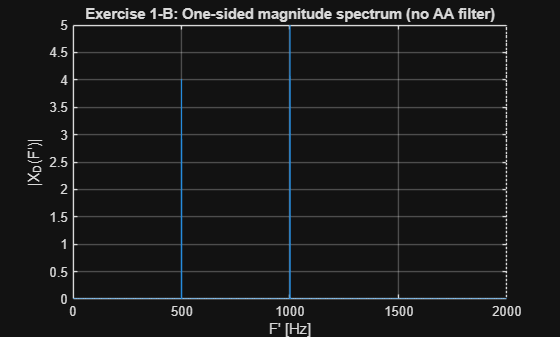


% ================================
% Spectra of down-sampled signal
% ================================
XD = fft(xD, ND);

% ---------- (1) One-sided spectrum (0..F_s''/2) – keep for later use ----------
XDmag   = abs(XD)/ND;
f_axisD = (0:ND-1)*Fs_D/ND;
fD_pos  = f_axisD(1:ND/2+1);
XDmag_pos = 2*XDmag(1:ND/2+1);

figure;
plot(fD_pos, XDmag_pos, 'LineWidth', 1.0); grid on; hold on;
xline(Fmax_D, ':k', 'F_{\max}''');
xlabel('F'' [Hz]');
ylabel('|X_D(F'')|');
title('Exercise 1-B: One-sided magnitude spectrum (no AA filter)');
xlim([0 Fs_D/2]);
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_1B_mag_downsampled_onesided.png'), 'Resolution', 300);

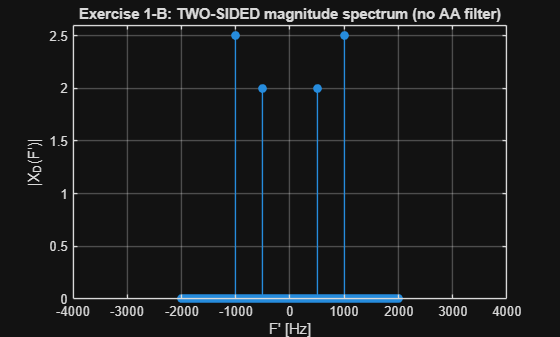


% ---------- (2) Two-sided spectrum (-F_s''/2..F_s''/2) for solution-sheet style ----------
XD_shift     = fftshift(XD);
XDmag_shift  = abs(XD_shift)/ND;
df_D         = Fs_D/ND;
f_axisD_2s   = (-ND/2:ND/2-1) * df_D;

figure;
stem(f_axisD_2s, XDmag_shift, 'filled'); grid on;
xlabel('F'' [Hz]');
ylabel('|X_D(F'')|');
title('Exercise 1-B: TWO-SIDED magnitude spectrum (no AA filter)');
xlim([-4000 4000]);      % here: [-2000 2000] Hz
ylim([0 2.6]);
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_1B_mag_downsampled_twosided.png'), 'Resolution', 300);

## Exercise 1-C & 1-D: Anti-aliasing LP design by Fourier-transform method

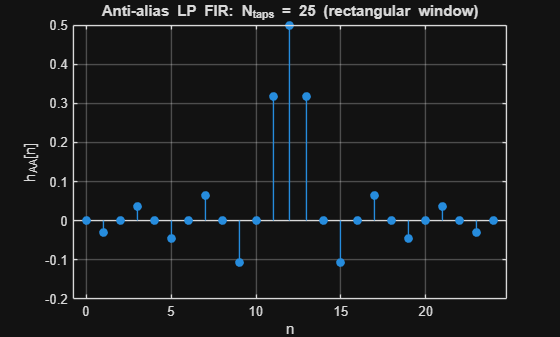

% AA filter specs
Fpass_AA = 1855;     % Passband [Hz]
Fstop_AA = 2145;     % Stopband [Hz]
AsdB_AA  = 20;       % Required stopband attenuation [dB]

% ---- Window / length calculation ----
DeltaF_sharp = (Fstop_AA - Fpass_AA)/Fs;      % (F_stop - F_pass)/F_s
Ntaps_AA     = ceil(0.9 / DeltaF_sharp);      % rectangular window rule
if mod(Ntaps_AA, 2) == 0
    Ntaps_AA = Ntaps_AA + 1;                  % force odd length
end
M_AA = Ntaps_AA - 1;
K_AA = M_AA/2;

% ---- Cutoff frequency ----
Fc_AA = 0.5*(Fpass_AA + Fstop_AA);           % 2000 Hz
wc_AA = 2*pi*Fc_AA/Fs;                       % rad/sample

% ---- Ideal LP impulse response (truncated & shifted to be causal) ----
nA          = 0:M_AA;
nA_centered = nA - K_AA;                     % -K..K
hAA_centered = (wc_AA/pi) * sinc((wc_AA/pi)*nA_centered);
b_AA         = hAA_centered;                 % FIR coefficients

% ---- Impulse response plot ----
figure;
stem(nA, b_AA, 'filled'); grid on;
xlabel('n');
ylabel('h_{AA}[n]');
title(sprintf('Anti-alias LP FIR: N_{taps} = %d (rectangular window)', Ntaps_AA));

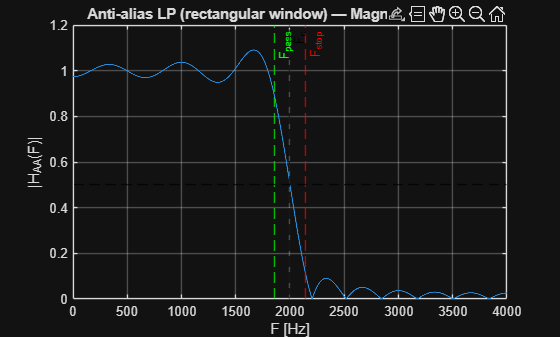


% ---- Frequency response (linear magnitude) ----
[H_AA, w_AA] = freqz(b_AA, 1, Nfft);         % w in [0, pi]
F_AA = w_AA*Fs/(2*pi);                       % map to [0, F_s/2] [Hz]

figure;
plot(F_AA, abs(H_AA), 'LineWidth', 1.0); grid on; hold on;
xline(Fpass_AA, '--g', 'F_{pass}');
xline(Fstop_AA, '--r', 'F_{stop}');
xline(Fc_AA,   '--k', 'F_c');                % cutoff frequency line
yline(0.5,     '--k');                       % |H(F_c)| = 0.5
xlabel('F [Hz]');
ylabel('|H_{AA}(F)|');
title('Anti-alias LP (rectangular window) — Magnitude response');
xlim([0 Fs/2]);
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_1C_AA_mag.png'), 'Resolution', 300);

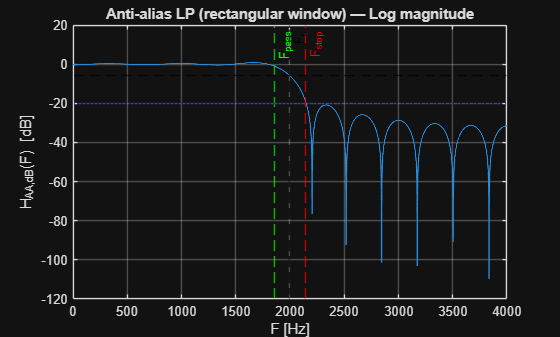


% ---- Log-magnitude response (dB) ----
HdB_AA = 20*log10(abs(H_AA)+eps);
Fc_dB  = 20*log10(0.5);                      % ≈ -6.02 dB

figure;
plot(F_AA, HdB_AA, 'LineWidth', 1.0); grid on; hold on;
xline(Fpass_AA, '--g', 'F_{pass}');
xline(Fstop_AA, '--r', 'F_{stop}');
xline(Fc_AA,   '--k', 'F_c');                % cutoff in freq
yline(Fc_dB,   '--k');                       % 20 log10(0.5)
yline(-AsdB_AA, ':b');                       % stopband spec (-20 dB)
xlabel('F [Hz]');
ylabel('H_{AA,dB}(F) [dB]');
title('Anti-alias LP (rectangular window) — Log magnitude');
xlim([0 Fs/2]);
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_1C_AA_logmag.png'), 'Resolution', 300);

## Exercise 1-D: Filter x[n] with AA-filter (no down-sampling yet)

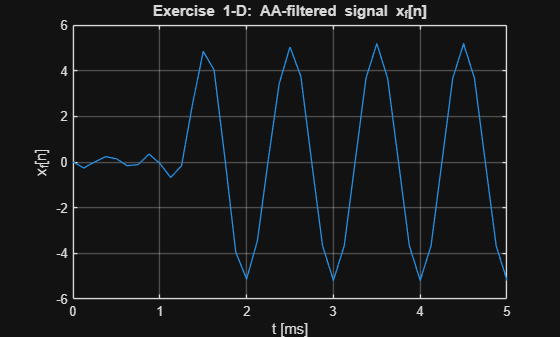

% AA-filtered signal (b_AA designed in Exercise 1-C)
x_filt = filter(b_AA, 1, x);

% --- Time-domain plot (same time axis as 1-A) ---
figure;
plot(t*1e3, x_filt, 'LineWidth', 1.0); grid on;
xlim([0 5]);                      % first 5 ms
xlabel('t [ms]');
ylabel('x_f[n]');
title('Exercise 1-D: AA-filtered signal x_f[n]');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_1D_time_filtered.png'), 'Resolution', 300);

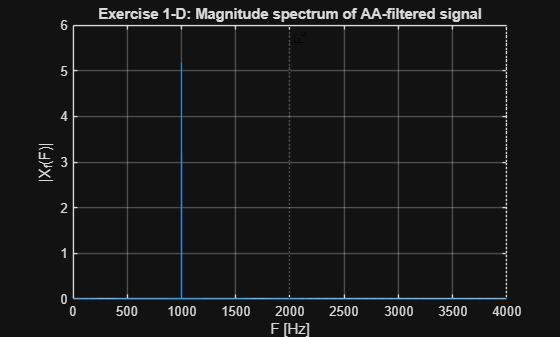


% --- Spectrum of the filtered signal ---
Nf         = numel(x_filt);
Xf         = fft(x_filt, Nf);
Xf_mag     = abs(Xf)/Nf;
F_axis_f   = (0:Nf-1)*Fs/Nf;
F_pos_f    = F_axis_f(1:Nf/2+1);
Xf_mag_pos = 2*Xf_mag(1:Nf/2+1);

figure;
plot(F_pos_f, Xf_mag_pos, 'LineWidth', 1.0); grid on; hold on;
xline(Fc_AA, ':k', 'F_c');        % Fc_AA defined in 1-C
xline(Fs/2, ':k', 'F_s/2');
xlabel('F [Hz]');
ylabel('|X_f(F)|');
title('Exercise 1-D: Magnitude spectrum of AA-filtered signal');
xlim([0 Fs/2]);
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_1D_mag_filtered.png'), 'Resolution', 300);

## Exercise 1-E: Down-sample the AA-filtered signal (M = 2)

M      = 2;                % down-sampling factor
Fs_D   = Fs/M;             % new sampling frequency [Hz]
Fmax_D = Fs_D/2;           % new Nyquist frequency [Hz]

fprintf('Exercise 1-E (after AA filter):\n');

Exercise 1-E (after AA filter):


fprintf('  Down-sampling factor M = %d\n', M);

  Down-sampling factor M = 2


fprintf('  New sampling rate F_s'' = %.0f Hz\n', Fs_D);

  New sampling rate F_s' = 4000 Hz


fprintf('  New Nyquist frequency F_{max}'' = %.0f Hz\n\n', Fmax_D);

  New Nyquist frequency F_{max}' = 2000 Hz



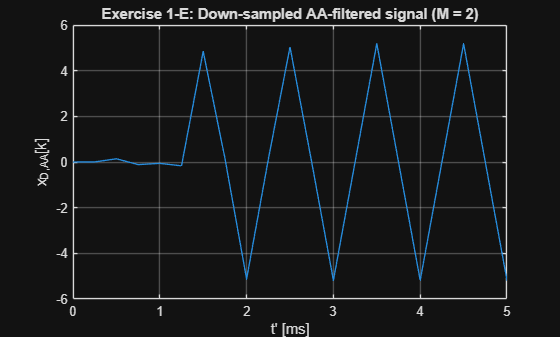


% Down-sampled, filtered signal x_{D,AA}[k] = x_filt[2k]
xD_AA = x_filt(1:M:end);
ND_AA = numel(xD_AA);
kD_AA = 0:ND_AA-1;
tD_AA = kD_AA/Fs_D;

% --- (a,b) Time-domain plot of x_{D,AA}[k] ---
figure;
plot(tD_AA*1e3, xD_AA, 'LineWidth', 1.0); grid on;
xlim([0 5]);
xlabel('t'' [ms]');
ylabel('x_{D,AA}[k]');
title('Exercise 1-E: Down-sampled AA-filtered signal (M = 2)');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_1E_time_downsampled_AA.png'), 'Resolution', 300);

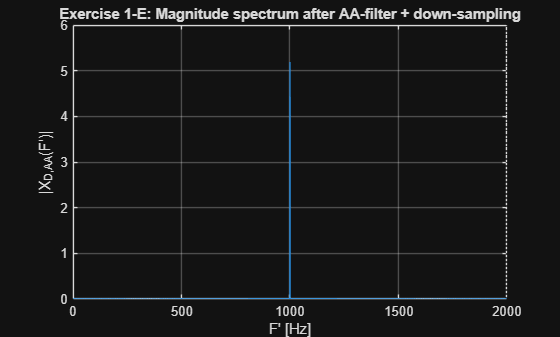


% --- (c) Spectrum of down-sampled, filtered signal ---
XD_AA      = fft(xD_AA, ND_AA);
XD_AA_mag  = abs(XD_AA)/ND_AA;
f_axisD_AA = (0:ND_AA-1)*Fs_D/ND_AA;
fD_AA_pos  = f_axisD_AA(1:ND_AA/2+1);
XD_AA_pos  = 2*XD_AA_mag(1:ND_AA/2+1);

figure;
plot(fD_AA_pos, XD_AA_pos, 'LineWidth', 1.0); grid on; hold on;
xline(Fmax_D, ':k', 'F_{\max}''');
xlabel('F'' [Hz]');
ylabel('|X_{D,AA}(F'')|');
title('Exercise 1-E: Magnitude spectrum after AA-filter + down-sampling');
xlim([0 Fs_D/2]);
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_1E_mag_downsampled_AA.png'), 'Resolution', 300);

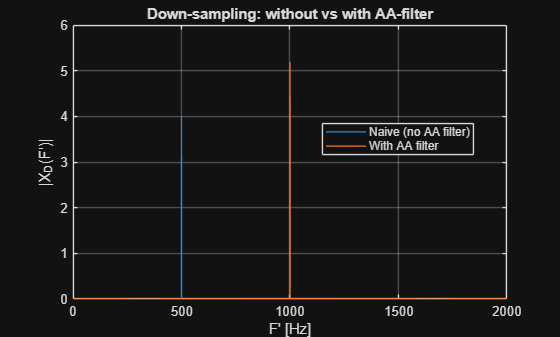


% --- (d) Comparison with naive 1-B result (requires xD, tD, fD_pos, XDmag_pos) ---
figure;
plot(fD_pos, XDmag_pos, 'LineWidth', 1.0); hold on;
plot(fD_AA_pos, XD_AA_pos, 'LineWidth', 1.0);
grid on;
xlabel('F'' [Hz]');
ylabel('|X_D(F'')|');
title('Down-sampling: without vs with AA-filter');
legend('Naive (no AA filter)', 'With AA filter', 'Location', 'best');
xlim([0 Fs_D/2]);
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_1E_downsample_compare.png'), 'Resolution', 300);

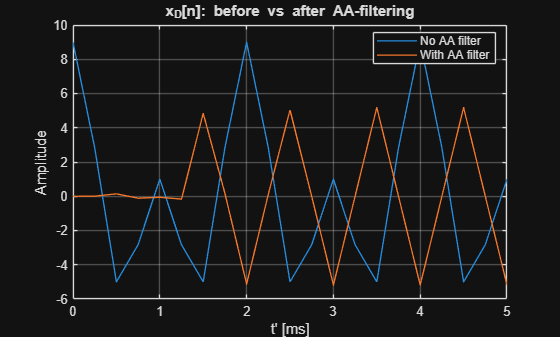


figure;
plot(tD*1e3, xD, 'LineWidth', 1.0); hold on;
plot(tD_AA*1e3, xD_AA, 'LineWidth', 1.0);
grid on;
xlabel('t'' [ms]');
ylabel('Amplitude');
title('x_D[n]: before vs after AA-filtering');
legend('No AA filter','With AA filter', 'Location', 'best');
xlim([0 5]);
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_1E_time_compare.png'), 'Resolution', 300);

## Exercise 2 — Up-sampling and interpolation (L = 3)

## Exercise 2-A: Up-sampling by L = 3 (zero-stuffing)

L = 3;                  % Up-sampling factor
Fs_U = L*Fs;            % New sampling frequency [Hz]
N_U  = L*N;             % Number of samples after up-sampling

fprintf('\nExercise 2-A/B:\n');


Exercise 2-A/B:


fprintf('  Up-sampling factor L = %d\n', L);

  Up-sampling factor L = 3


fprintf('  New sampling rate F_s^{(U)} = %.0f Hz\n', Fs_U);

  New sampling rate F_s^{(U)} = 24000 Hz


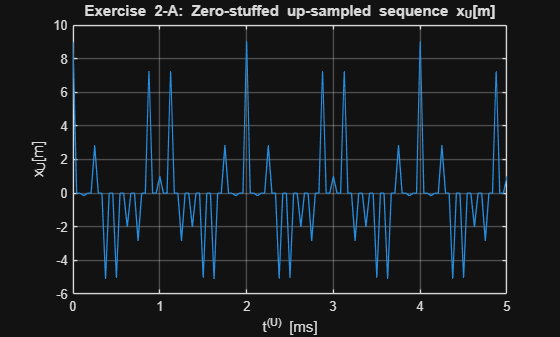


% Zero-stuffing: x_U[m] = { x[n], m = nL; 0, otherwise }
xU = zeros(1, N_U);
xU(1:L:end) = x;

nU = 0:N_U-1;
tU = nU/Fs_U;

% Time-domain (short window)
figure;
plot(tU*1e3, xU, 'LineWidth', 1.0); grid on;
xlim([0 5]);     % first 5 ms
xlabel('t^{(U)} [ms]');
ylabel('x_U[m]');
title('Exercise 2-A: Zero-stuffed up-sampled sequence x_U[m]');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_2A_upsampled_time.png'), 'Resolution', 300);

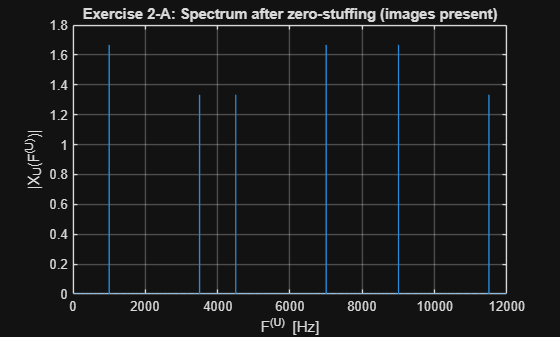


% Spectrum of zero-stuffed sequence
Nfft_U  = N_U;
f_axisU = (0:Nfft_U-1)*Fs_U/Nfft_U;
XU      = fft(xU, Nfft_U);
XUmag   = abs(XU)/Nfft_U;
fU_pos  = f_axisU(1:Nfft_U/2+1);
XU_pos  = 2*XUmag(1:Nfft_U/2+1);

figure;
plot(fU_pos, XU_pos, 'LineWidth', 1.0); grid on;
xlabel('F^{(U)} [Hz]');
ylabel('|X_U(F^{(U)})|');
title('Exercise 2-A: Spectrum after zero-stuffing (images present)');
xlim([0 Fs_U/2]);
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_2A_upsampled_spectrum.png'), 'Resolution', 300);

## Exercise 2-B/C/D: Interpolation LP via Parks–McClellan (firpm)

% Specification (from slides / exercise):
Fpass_I = 3500;         % Passband edge [Hz]
Fstop_I = 4500;         % Stopband [Hz]
delta1  = 0.05;         % Passband ripple
delta2  = 0.02;         % Stopband ripple

% Normalised digital frequencies for the design (rad/sample at Fs_U)
omega_p = 2*pi*Fpass_I/Fs_U;
omega_s = 2*pi*Fstop_I/Fs_U;
Delta_w = omega_s - omega_p;
delta   = min(delta1, delta2);      % worst-case ripple
A_dB    = -20*log10(delta);

% Empirical order estimate for equiripple LP:
M_est = ceil((A_dB - 7.95)/(2.285*Delta_w));  % Oppenheim/Hamming formula
% Make order even (for Type I linear-phase => odd number of taps)
if mod(M_est, 2) ~= 0
    M_est = M_est + 1;
end
Ntaps_I = M_est + 1;

fprintf('Exercise 2-B:\n');

Exercise 2-B:


fprintf('  omega_p = %.3f rad/sample, omega_s = %.3f rad/sample\n', ...
        omega_p, omega_s);

  omega_p = 0.916 rad/sample, omega_s = 1.178 rad/sample


fprintf('  A_dB = %.2f dB, Δω = %.4f rad/sample\n', A_dB, Delta_w);

  A_dB = 33.98 dB, Δω = 0.2618 rad/sample


fprintf('  Estimated interpolation filter order M ≈ %d (N_taps = %d)\n', ...
        M_est, Ntaps_I);

  Estimated interpolation filter order M ≈ 44 (N_taps = 45)


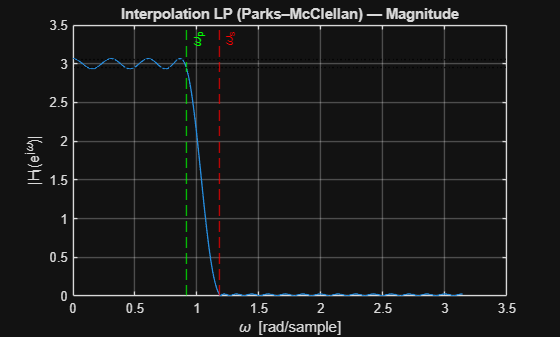


% Parks–McClellan (firpm) uses normalised freq 0..1 <=> 0..F_Nyq
F_Nyq_U     = Fs_U/2;
Fpass_normI = Fpass_I / F_Nyq_U;
Fstop_normI = Fstop_I / F_Nyq_U;

f_firpm = [0 Fpass_normI Fstop_normI 1];   % bands
a_firpm = [L L 0 0];                       % desired gain (L in passband)
w_firpm = [1/delta1 1/delta2];             % weights

b_I = firpm(M_est, f_firpm, a_firpm, w_firpm);

% Frequency response of interpolation filter
[H_I, w_I] = freqz(b_I, 1, Nfft_U);
figure;
plot(w_I, abs(H_I), 'LineWidth', 1.0); grid on; hold on;
xline(omega_p, '--g', '\omega_p');
xline(omega_s, '--r', '\omega_s');
yline(L+delta1, ':k');
yline(L-delta1, ':k');
xlabel('\omega [rad/sample]');
ylabel('|H_I(e^{j\omega})|');
title('Interpolation LP (Parks–McClellan) — Magnitude');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_2B_interp_filter_mag.png'), 'Resolution', 300);

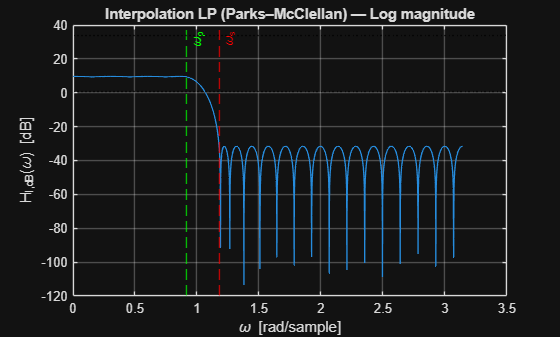


% Log-magnitude
HdB_I = 20*log10(abs(H_I)+eps);
figure;
plot(w_I, HdB_I, 'LineWidth', 1.0); grid on; hold on;
xline(omega_p, '--g', '\omega_p');
xline(omega_s, '--r', '\omega_s');
yline(-20*log10(1-delta1), ':k');  % approx passband bound
yline(-20*log10(delta2), ':k');    % stopband bound
xlabel('\omega [rad/sample]');
ylabel('H_{I,dB}(\omega) [dB]');
title('Interpolation LP (Parks–McClellan) — Log magnitude');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_2B_interp_filter_logmag.png'), 'Resolution', 300);

## Exercise 2-E/F: Filter zero-stuffed signal and inspect spectrum

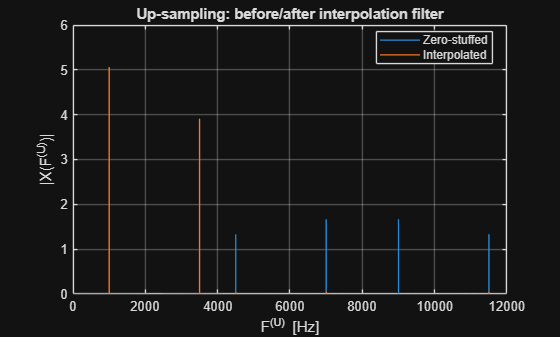

% Filtered, up-sampled signal (interpolated)
xU_filt = filter(b_I, 1, xU);

% Spectrum of interpolated signal
XU_filt   = fft(xU_filt, Nfft_U);
XU_filt_m = abs(XU_filt)/Nfft_U;
XU_f_pos  = 2*XU_filt_m(1:Nfft_U/2+1);

figure;
plot(fU_pos, XU_pos, 'LineWidth', 1.0); hold on;
plot(fU_pos, XU_f_pos, 'LineWidth', 1.0);
grid on;
xlabel('F^{(U)} [Hz]');
ylabel('|X(F^{(U)})|');
title('Up-sampling: before/after interpolation filter');
legend('Zero-stuffed','Interpolated','Location','best');
xlim([0 Fs_U/2]);
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_2E_interp_compare_spectrum.png'), 'Resolution', 300);

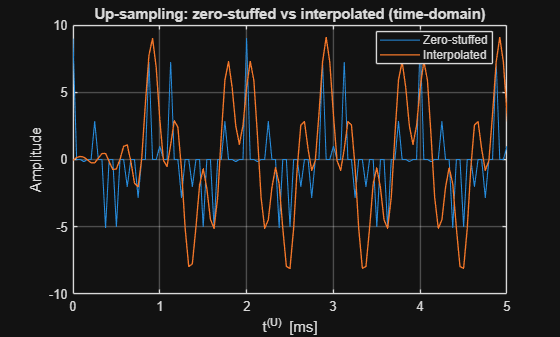


% Time-domain (short window) to see smoother waveform
figure;
plot(tU*1e3, xU, 'LineWidth', 0.8); hold on;
plot(tU*1e3, xU_filt, 'LineWidth', 1.0);
grid on;
xlim([0 5]);
xlabel('t^{(U)} [ms]');
ylabel('Amplitude');
title('Up-sampling: zero-stuffed vs interpolated (time-domain)');
legend('Zero-stuffed','Interpolated','Location','best');
exportgraphics(gcf, fullfile(imgDir, ...
    'DSP_U12_Tirsdag_2E_interp_compare_time.png'), 'Resolution', 300);